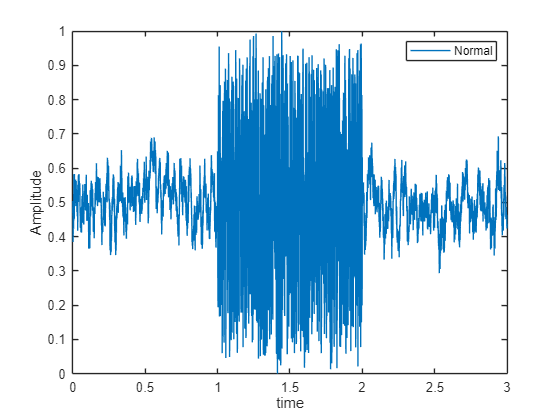

data = load("data.mat");
time_series = data.time_series;
clear data;

% Normalized Data with 2 diffrent ways
normalizedData = normalize(time_series,"range");
normalizedData2= (time_series - min(time_series))/(max(time_series)-min(time_series));

time = ((0:length(normalizedData)-1)/1000) ;
time=time(:);

normalizedData_plot = plot(time,normalizedData,"DisplayName","Normal");
xlabel("time")
ylabel("Amplitude")
legend

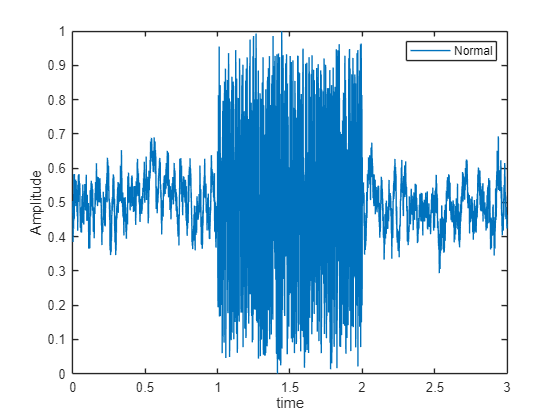


normalizedData_plot2 = plot(time,normalizedData2,"DisplayName","Normal");
xlabel("time")
ylabel("Amplitude")
legend

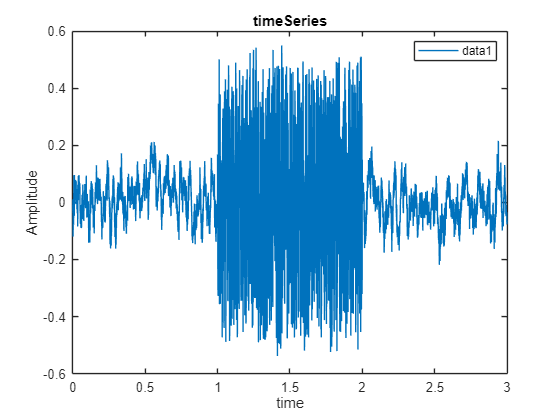


time_series_plot= plot(time,time_series);
xlabel("time")
ylabel("Amplitude")
title("timeSeries")
legend


function coefficients = fourier_series_coe(x, n)
    L = length(x);
    coefficients=zeros(1,n);
    for k = 0:n-1
        for m = 1:L
            coefficients(k+1) = coefficients(k+1) + (x(m) * exp(-1j*k*2*pi*(m-1)/L))*(1000/L);
        end
    end
end

middle_data =zeros(1000,1);
for t=1:1000
    middle_data(t)=normalizedData(t+1000);
end

fundemental_freq = 1;
coefficients =fourier_series_coe(middle_data,1000);
frequency=zeros(size(coefficients));

for m= 1:1000
    frequency(m)=m*fundemental_freq;
end

low_freq=frequency<10;
low_freq_coeff = coefficients(low_freq);

figure;
stem(frequency(low_freq), abs(low_freq_coeff));

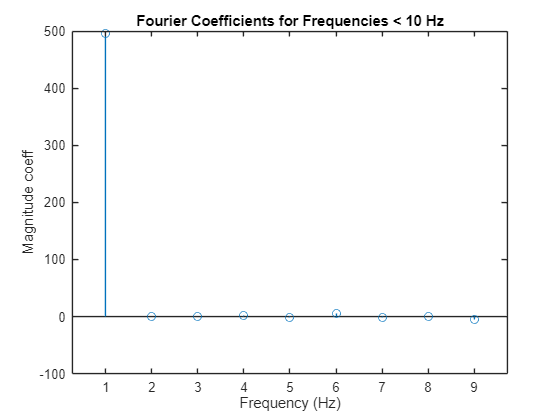

title('Fourier Coefficients for Frequencies < 10 Hz');
xlabel('Frequency (Hz)');
ylabel('Magnitude coeff');

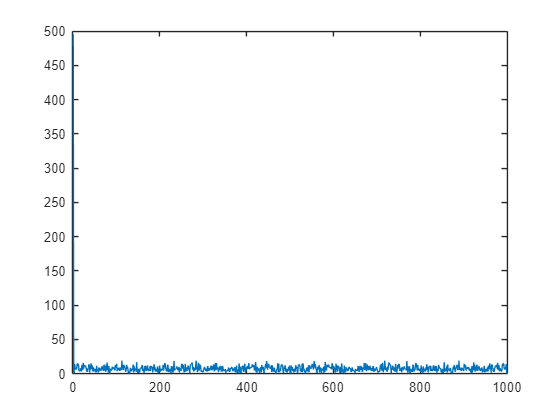

plot(frequency,abs(coefficients))